# **Shor's Algorithm**

**Pietro Lanna, Simone Pellegatta, Matteo Rossi**

## 1 Introduction

### 1.1 Reason for the Project

The rapid growth of quantum computing has revolutionized the field of computational science, presenting new paradigms for solving problems previously considered intractable. Among these, Shor’s algorithm stands out as one of the most significant breakthroughs, offering a quantum solution to the problem of integer factorization. This project aims to delve into the theoretical foundations of Shor’s algorithm, offering a way to interact with it through MATLAB Support Package for Quantum Computing, analyze its computational implications, and its real-world applications.

### 1.2 Overview of Shor’s Algorithm

Shor’s algorithm, introduced by Peter Shor in 1994, leverages the principles of quantum mechanics to efficiently solve the factorization problem in a a polynomial time with bounded probability. It combines quantum interference phenomena with classical computation techniques. This synergy of quantum and classical methods not only accelerates computation but also highlights the unique capabilities of quantum systems. Shor’s algorithm represents a milestone in quantum algorithms, setting the stage for further developments in quantum cryptography and computational complexity.

## 2 Theoretical Background

### 2.1 Classification of Problems: P, NP and NP-Complete

Computational problems are categorized based on their complexity, which reflects the resources (time and space) required to solve them as a function of input size. The key classes are:

- $P$ (Polynomial Time): Problems in $P$ can be solved by a deterministic classical computer in polynomial time. Examples include sorting a list or finding the greatest common divisor. These problems are considered “easy” for classical computers.

- $NP$ (Nondeterministic Polynomial Time): Problems in $NP$ are those for which a proposed solution can be verified in polynomial time, even if finding the solution is not necessarily efficient. Examples include the *Traveling Salesman Problem* and *Integer Factorization*.

- $NP-Complete$: These are the hardest problems in $NP$, to which any other problem in $NP$ can be reduced in polynomial time. Solving an $NP-Complete$ problem efficiently would imply that all $NP$ problems can be solved efficiently. Examples include the *Boolean Satisfiability Problem* (SAT) and the *Knapsack Problem*.

The relationship between these classes is an open question in computational complexity theory. If $P=\textrm{NP}$, it would mean that every problem in $NP$ has a polynomial-time solution, which would revolutionize fields like cryptography and optimization.

### 2.2 Quantum Computing: Foundations and Principles

Quantum computing leverages the principles of quantum mechanics, offering a revolutionary approach to processing information. Unlike classical bits, quantum computers use qubits, which can exist in a superposition of states $$\ket{0}$$ and $$\ket{1}$$, enabling them to process vast amounts of information simultaneously.

Quantum Gates manipulate qubits through unitary transformations, analogous to classical logic gates. Key gates include the *Hadamard gate* (for superposition), the *Pauli-X gate* (for flipping states) and the *CNOT gate* (for entanglement). These gates serve as the foundation for quantum circuits that execute complex algorithms, such as Shor’s algorithm.

The principles of superposition and interference enable quantum computers to amplify correct solutions while canceling incorrect ones, making them uniquely suited to solving problems like integer factorization with exponential speedup over classical methods. 

## 3 How Shor's Algorithm Works

Shor's Algorithm addresses a specific type of problem which consists of finding the integer factors of a given odd composite number $N$. 

The algorithm consists of two main steps:

-  A classical reduction in factorizing an integer $N$ into an order-finding problem. 

- A quantum algorithm to solve the order-finding problem.

### 3.1 Classical Reduction

A complete factorization algorithm can be achieved by efficiently factoring an arbitrary integer $N$ into just two integers $p$ and $q$ greater than $1$ such that $N = pq$. If either $p$ or $q$ are not prime, then the process can be repeated on those factors until all resulting factors are prime numbers.

Classically, we can efficiently determine whether $N$ is even or a prime power. Hence, let's assume that $N$ is odd and that is not a prime power.

Next, we randomly choose an integer $a$ such that $1 < a < N$. A potential nontrivial divisor of $N$ can be found by computing  $b = gcd(a,N)$, where $gcd$ denotes the Greatest Common Divisor, which can be computed classically using the Euclidean Algorithm: 

- If the greatest common divider is nontrivial (i.e., $b \neq 1$), the algorithm has successfully found a nontrivial factor of $N$, and the other nontrivial factor is $\frac{N}{b}$.

- If a nontrivial factor is not found (i.e., $b = 1$), then $N$ and the choice of $a$ are coprime (meaning the only common divisor is 1). In this case, $a$ has a multiplicative order $r$ modulo $N$, meaning:


$$a^r \equiv 1 \space mod\space N$$


where $r$ is the smallest positive integer that satisfies this congruence.

The quantum algorithm is then used to find $r$. Hence $N$ divides $a^r -1$,  which can be written as follows: 


$$N \space|\space a^r -1 = N \space|\space (a^{\frac{r}{2}} - 1) (a^{\frac{r}{2}} + 1)$$


So, the algorithm cannot proceed if $r$ is odd, because $a^{\frac{r}{2}}$ must be an integer, in this case the algorithm would have to restart with a new $a$. Therefore, we will assume $r$ is even. The next step is to compute: 


$$d = gcd(N, a^{\frac{r}{2}} - 1)$$


- if $d = 1$, it implies  $N \space|\space(a^{\frac{r}{2}} + 1)$  was true, and no nontrivial factor of $N$ can be found using $a$. The algorithm must restart with a new $a$. 

- if $d \neq 1$, $d$ is a non-trivial factor of $N$, and the other factor is $\frac{N}{d}$. The algorithm then ends up being successfully terminated. 

#### 3.1.1 Algorithm Summary

Let $N$ be odd, and not a prime power. We want to output two nontrivial factors of $N$.

- Pick a random number $a$ such that $1 < a < N$.

- Compute $b = gcd(a,N)$, the greatest common divisor of $a$ and $N$.

- If $b \neq 1$, then $b$ is a nontrivial factor of $N$, with the other factor being $\frac{N}{b}$. Exit.

- If $b = 1$, use the quantum subroutine to find the order $r$ of $a$ modulo $N$.

- If $r$ is odd, then go back to step 1.

- Compute $d = gcd(N, a^{\frac{r}{2}} + 1)$.

- If $d = 1$, go back to step 1.

- If $d \neq 1$, $d$ is a nontrivial factor, and $\frac{N}{d}$ is the other factor. Exit.

### 3.2 Quantum Order-Finding Subroutine

The goal of the quantum subroutine of Shor's Algorithm is, given coprime integers $N$ and $a$ such that $1<a<N$, to determine the order $r$ of $a$ modulo $N$, which is the smallest positive integer such that $a^r \equiv 1 \; (\text{mod}\ N)$; if no such integer exists, the order is said to be infinite.

To achieve this, *Shor's Algorithm* uses a quantum circuit involving two registers. The size of the first register determines how accurate of an approximation the circuit produces. 

Assuming that $n$ is the smallest integer such that $N \leq 2^n$ which means $n = \lceil{\log_2{N}}\rceil$, it can be shown that using $2n$ qubits gives sufficient accuracy to find $r$. The size of the second register uses $n$ qubits.

The following description of the algorithm uses bra-ket notation to denote quantum states and $\otimes$ to denote the tensor product. The quantum algorithm consist of two main steps:

- Apply *quantum phase estimation* using the unitary $U$ that corresponds to the operation of multiplying by $a$ (modulo $N$). The input state is $|{0\rangle }^{\otimes 2n} \otimes |1\rangle$, where $\ket{1}$ represents the second register of $n$ qubits, and $|{0\rangle }^{\otimes 2n} =|0\rangle \otimes |0\rangle \otimes \cdots \otimes |0\rangle$ represents the first register of $2n$ qubits. The eigenvalues of $U$ encode information about the period, and $\ket{1}$ can be expressed as a sum of its eigenvectors. The output of the quantum phase estimation step is a random integer of the form $\frac{j}{r} 2^{2n}$, where $j$ is a random integer in the range $0, 1, \dots, r-1$.

- Use the continued fractions algorithm to extract the period $r$ from the results obtained in the previous measurement. This classical algorithm processes the data from the quantum state measurement to retrieve the period.

#### 3.2.1 Quantum Phase Estimation

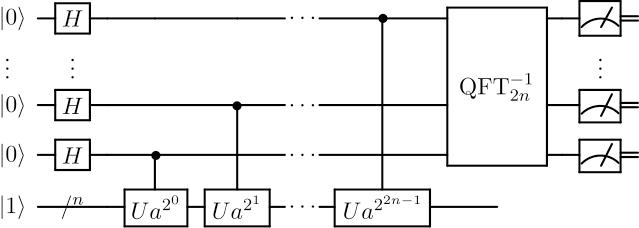

Figure 1: Quantum subroutine in Shor’s Algorithm

The goal of Q*uantum Phase Estimation* is to estimate the phase $\theta$ associated with the unitary operator $U$ acting on an eigenstate $\ket{\psi}$ such that 

$U|\psi \rangle =e^{2\pi i\theta } |\psi \rangle$.

The *QPE* algorithm starts with a composite quantum state: one part is a control register (initialized with $2n$ qubits in the $\ket{0}$ state) to record the phase, and the other part contains the eigenstate $\ket{\psi}$ of the unitary operator $U$. Through a sequence of quantum operations, the *QPE* algorithm creates a superposition in which the phase information is encoded into the control register. The first step of the algorithm applies an *Hadamard* gate to each qubit in the control register, creating an equal superposition of all possible  computational basis states. The combined state becomes:


$$\frac{1}{\sqrt{2^n }}\sum_{k=0}^{2^n -1} |k\rangle \otimes |\psi \rangle$$


where $\ket{\psi}$ represents the binary states of the $n-qubit$ control register.

Next, the algorithm applies controlled-unitary operations. Specifically, for each qubit in the control register, a controlled $U^{2^j}$ is applied, where $j$ depends on the position of the qubit in the register. These operations entangle the control register with the phase information of the unitary operator $U$. For an eigenstate $\ket{\psi}$, where the action of the controlled-unitary gates introduces phase factor into superposition:


$$\frac{1}{\sqrt{2^n }}\sum_{k=0}^{2^n -1} |k\rangle \otimes U^k |\psi \rangle =\frac{1}{\sqrt{2^n }}\sum_{k=0}^{2^n -1} e^{2\pi i\theta k} |k\rangle \otimes |\psi \rangle \;$$


The procedure to implement a controlled - $U^{2^j }$ operation for any integer $j$ is obtained by using the modular exponentiation, which will be described in section 3.4 Modular Exponentiation.

At this point, the phase information $\theta$ has been encoded into the amplitude of the  states in the control register.

However, the phase information is not directly measurable in this form. To extract $\theta$, the *QPE* algorithm applies the *Quantum Fourier Transform *(*QFT*) to the control register. The *QFT* efficiently transforms the phase-encoded amplitudes into a state where the phase $\theta$ is mapped to a binary approximation of $2^n \cdot \theta$. After applying the *QFT*, the control register is ready for measurement, and the outcome provides the desired information about $\theta$.

The $U$ gate defined above satisfies $U^r = I$, which implies that its eigenvalues are the $r-th$ roots of unity $w^{k}_{r} = e^{2\pi i k/r}$. 

Furthermore, using *quantum phase estimation* on an input state $|{0\rangle }^{\otimes 2n} \otimes |\psi_j \rangle$ would then return the integer $2^{2n} \frac{j}{r}$ with high probability.

 In conclusion, using *QPE* we can get a good estimation for $\frac{j}{r}$.

#### 3.2.2 The Role of Inverse Quantum Fourier Transform in QPE

The Inverse Quantum Fourier Transform ${\textrm{QFT}}^{\dagger}$ is a quantum operation that essentially reverses the action of the Quantum Fourier Transform. 

While the QFT maps from the computational basis to the Fourier basis, the ${\textrm{QFT}}^{\dagger}$ maps from the Fourier basis back to the computational basis.

**Mathematical Foundation**

In order to offer a general overview of the routine, using a general notation:

We run the phase estimation procedure with the state $|1\rangle$ in place of one of the eigenvectors $|\psi_k \rangle$. 

After the Quantum Fourier transform is performed, this leaves us with the state:


$$
$$
\frac{1}{\sqrt{r}} \sum_{k=0}^{r-1} |\psi_k\rangle |\gamma_k\rangle,
$$

$$
 

where:


$$|\gamma_k \rangle =\frac{1}{2^n }\sum_{y=0}^{2^n -1} \sum_{x=0}^{2^n -1} e^{2\pi ix(k/r-y/2^n )} |y\rangle \ldotp$$


The vector $|\gamma_k \rangle$ represents the state of the top $n$ qubits after the inverse of the quantum Fourier transform has been performed.

Recalling that $\lbrace |\psi_0 \rangle ,\ldots,|\psi_{r-1} \rangle \rbrace$ is an orthonormal set, we find that a measurement of the top $n$ qubits yields an approximation $y/2^n$ to the value $k/r$ where $k\in \lbrace 0,\ldots,r-1\rbrace$ is chosen uniformly at random.

 This allows us to learn $r$ with a high degree of confidence after several independent runs, which in this specific simulation has been set to 2048, and a small amount of classical computation. 

**Circuit Implementation Details**

The  circuit implementing the inverse QFT consists of two main parts:

- **Bit Reversal (SWAP Operations)**: The first loop implements qubit reversal through SWAP gates (constructed using three CNOT gates for each swap). This reverses the qubit ordering from little-endian to big-endian convention or vice versa.

- **Phase Rotations and Hadamard Gates**: The second part applies controlled-rotation gates with negative angles (-π/2^(j-m)) followed by Hadamard gates. This performs the actual inverse Fourier transformation on the quantum state.

Note that the circuit can also be implemented by using the native functions of the package: [`inv`](https://it.mathworks.com/help/matlab/ref/quantumcircuit.inv.html)`(`[`qftGate`](https://it.mathworks.com/help/matlab/ref/qftgate.html)`(qubits))`, but endianness has to be taken into account (the measurement of the upper register will be inverted).

**Geometric Interpretation**

Geometrically, the ${\textrm{QFT}}^{\dagger}$ can be visualized as "unwrapping" the phase information that was encoded in the quantum state by the quantum phase estimation procedure. The phase rotations in our circuit gradually disentangle the phase information that was spread across multiple qubits, allowing us to extract the binary representation of the phase as classical measurement outcomes.


% Inverse Quantum Fourier Transform (QFT†)
% 
% Implementation notes:
% - Endianness: Explicit qubit reversal is performed via SWAP gates (CX triplets) 
%    in the first loop, converting between bit-ordering conventions.
% - Phase rotations: Implements time-reversed QFT using negative angles (-π/2^{k}),
%    equivalent to adjoint CR1 gates.
% 
% Inputs:
%   n - Number of qubits in measurement register
%   mapping - Qubit index mapping defining physical implementation layout
% 
% Extra:
%   In order to make the function parametric in the number of qubits,
%   handling also odd numbers of n, the upper bound for q = 1:<n/2> has to be replaced with floorDiv(n,2)


function invQftGate = qftDaggerGate(n, mapping)

    gates = [];

    for q = 1:n/2  
        gates = [gates, cxGate(q, n-q+1)];
        gates = [gates, cxGate(n-q+1, q)];
        gates = [gates, cxGate(q, n-q+1)];
    end

    for j = 1:n
        for m = 1:j-1
            gates = [gates, cr1Gate(m, j, -pi/2^(j-m))];
        end
        gates = [gates, hGate(j)];
    end

    invQftGate = compositeGate(gates, mapping, "Name", "QFT_Dagger");
end

### 3.3 Classical Extraction of the Period via Continued Fractions

**1. Ideal Case (Period is a Power of 2)**

When the period $r\;$happens to be a power of $2$, the Quantum Fourier Transform (QFT) produces* exact integer multiples* of $\frac{Q}{r}$, where $Q=2^n$(the QFT dimension). 

 Here, the measured value $v$ directly satisfies: $v=$ $k\frac{2^n }{r}$, for some integer $k$. Most of the time $k,r$ will be relatively prime, in which case reducing $\frac{v}{2^n }$ will yield a fraction $\frac{j}{r}$ whose denominator is the period $r$. 

 **2. General Case (Arbitrary Periods **$r\not= 2^n \;$**for some n)**

For arbitrary periods $r$, the QFT output $v$ approximates (but does not exactly equal) a multiple of $\frac{2^n }{r}$. 

To recover $r$:

- Compute the normalized phase $\phi =\frac{v}{2^n }$.

- Find the best rational approximation $\frac{k}{r}$ to $\phi$, where $r<N\ldotp$

- Return $r\;$as the candidate period.

Shor shows that with high probability $v$ is within $\frac{1}{2}$ of some multiple of $\frac{2^n }{r}$ , say $k\frac{2^n }{r}$ . The reason why $n$ was chosen to satisfy $N^2 \le 2^n \le 2N$ becomes apparent when we try to extract the period r from the measured value v. In the high-probability case that $\left|\;v-k\frac{2^n }{r}\;\right|<\frac{1}{2}\;$for some $k$, the left inequality $N^2 \le 2^n$ implies that $\left|\;\frac{v}{2^n }-\frac{k}{r}\;\right|<\frac{1}{2\cdot 2^n }\le \frac{1}{2N^2 }$. In general, the difference between two distinct fractions $\frac{p}{q}$ and $\frac{p^{\prime } }{q^{\prime } }$ with denominators less than $N$ is bounded:

$\left|\;\frac{p}{q}-\frac{p^{\prime } }{q^{\prime } }\;\right|=\left|\;\frac{{p\;q}^{\prime } -p^{\prime } \;q}{q\;q^{\prime } }\;\right|>\frac{1}{N^2 }$.

Thus, there is at most one fraction $\frac{p}{q}$ with denominator $q<N$ such that $\left|\;\frac{v}{2^n }-\frac{p}{q}\;\right|<\frac{1}{N^2 }$. In the high probability case that $v$ is within $\frac{1}{2}$ of $k\frac{2^n }{r}$, this fraction will be $\frac{k}{r}$. The fraction $\frac{p}{q}$ can be computed using a continued fraction expansion. We take the denominator $q$ of the obtained fraction. as our guess for the period. The method succeeds with high probability when $k,r$ are coprime (occurs frequently due to random measurement outcomes).

**Continued Fraction Expansion**

The unique fraction with denominator less than $N$ that is within $\frac{1}{N^2 }$ of $\frac{v}{2^n }$ can be obtained efficiently from the continued fraction expansion of $\frac{v}{2^n }$ as follows. 

Let $\left\lfloor x\right\rfloor$ be the greatest integer less than $x$. Using the sequences:


$$a_o =\left\lfloor \frac{v}{2^n }\right\rfloor ,\;\;\;\;\;e_o =\frac{v}{2^n }-a_o$$



$$a_i =\left\lfloor \frac{1}{e_{i-1} }\right\rfloor ,{\;\;\;e}_i =\frac{1}{e_{i-1} }-a_i$$


By writing: $p_0 =a_0 ,{\;\;p}_1 =a_1 a_0 +1$

                  
$$p_i =a_i \;p_{i-1} +p_{i-2}$$


and:           $q_0 =1,\;q_i =a_1$

                  
$$q_i =a_i \;q_{i-1} +q_{i-2}$$


 compute the first fraction $\frac{p_i }{q_i }$ such that $q_i <N<q_{i+1}$.


function r = continued_fraction_period(value, Q)
% CONTINUED_FRACTION_PERIOD Estimates period using continued fractions method
%
%   r = continued_fraction_period(value, Q) computes the candidate period r
%   by finding the best rational approximation to value/Q using continued
%   fractions.
%
%   Inputs:
%     value : Integer measurement result from quantum circuit
%     Q     : Modulus for continued fraction approximation (2^num_phase_qubits)
%
%   Output:
%     r     : Candidate period for factorization
%
%   Note:
%     - Uses rat() with fixed tolerance 1e-6

    normalized_phase = value / Q;
   
    % Use rat to get the best rational approximation
    [~, denom] = rat(normalized_phase, 1e-6);
    
    % The denominator is our candidate period
    r = denom;
end


### 3.4  Modular Exponentiation

**The Phase Kick-Back Phenomenon**

A simple approach to phase estimation utilizes the phase kick-back phenomenon. This represents essentially a single-qubit version of the general phase estimation procedure.

When we apply a controlled-$U$ operation where the control qubit is in superposition, and the target register is in an eigenstate $|\psi \rangle$ of $U$ with eigenvalue $\lambda =e^{2\pi i\theta }$, a fascinating effect occurs: the phase information "kicks back" to the control qubit:


$$\frac{1}{\sqrt{2}}\left(|0\rangle \;+\;|1\rangle \right)\otimes |\psi \rangle \longrightarrow$$
  
$$\left(|0\rangle \;+e^{2\pi i\theta } |1\rangle \right)\otimes |\psi \rangle$$


This phase kick-back forms the foundation of quantum phase estimation.

**Building Controlled Operations**

To implement phase estimation, we need to construct controlled versions of our unitary operator $U$. We can create a circuit for a controlled-$U$ operation by adding a control qubit to the circuit for $U$, and then replacing every gate in $U$'s circuit with a controlled version of that gate, as it is shown in the circuit implementation below. Our new control qubit effectively controls every gate in the circuit for $U$.

**Multi Qubit-Phase Estimation**

When we extend phase estimation to use multiple control qubits, we gain more precision in our estimate of $\theta$. Consider a circuit where we apply controlled-$U^{2^j }$ operations for different values of $j$:

If $|\psi \rangle$ is an eigenvector of $U$ with eigenvalue $\lambda =e^{2\pi i\theta }$, then it's also an eigenvector of $U^{2^j }$ with eigenvalue $\lambda^{2^j } =e^{2\pi i\left(2^{j\theta } \right)}$.

When we apply controlled-$U^{2^j }$ operations with different powers, we're effectively probing different bits in the binary expansion of $\theta$. If we represent $\theta$ in binary as:


$$\theta =0\ldotp a_1 a_2 a_3 \ldotp \ldotp \ldotp$$


Then doubling $\theta$ shifts the binary point one position to the right:


$$2\theta =a_1 \ldotp a_2 a_3$$


This allows us to extract individual bits of the phase $\theta$ through careful measurement.

**Application to Order Finding**

For the purposes of quantum order-finding, we use the unitary operator $U\left(a\right)$ defined by its action on a computational basis states $\ket{\psi}$, where:


$$\begin{cases} 
\ket{ak \; \text{(mod N)}} & \quad 0 \leq k < N, \\
\ket{k} & \quad N \leq k < 2^n,
\end{cases}
\]$$


where $a$ is an integer relatively prime modulo $N$(For brevity, we will still refer to $U\left(a\right)$ as $U$).

**Using Non-Eigenvectors**

Interestingly, for order finding, we don't need to prepare eigenvectors of $U$. Instead, we can run the phase estimation procedure on the state $|1\rangle$ (the $n$-bit binary encoding of the number 1, based on the size of $U$). This works because $|1\rangle$ can be expressed as a uniform superposition of the eigenvectors of $U$:

 
$$|1\rangle =\frac{1}{\sqrt{r}}\;\sum_{k=0}^{r-1} |\psi_k \rangle$$


where $r$ is the order of $a\;\mathrm{mod}\;N$and $|\psi_k \rangle$ are the eigenvectors of $U$.

This gate, in conjunction with the Inverse Quantum Fourier Transform, completes the Order-Finding subroutine inside Shor's algorithm.

#### 3.4.1 A Compiled Implementation of U for a Specific Case

Implementing a *generic* controlled modular exponentiation circuit is computationally expensive for quantum simulations, indeed, it is the most demanding part of the algorithm. Several works about this topic are available, such as [1], [2].

Instead, we leverage problem-specific optimizations for our chosen parameters ($a=7,N=15$) to create a simplified, compiled circuit.

A *compiled circuit* can be seen as an optimized version of the generic component, specifically desgined to solve the desired instance of the problem, where the number of gates involved is reduced to a reasonable small quantity to simplify design and simulation.

In particular, by choosing the base $a=7$, which is known to factor $N=15$, we are able to build a compiled version for the function $U\left(a=7\right)$, defined by the equation: $U\left(a\right):|x_i \rangle \;|0\rangle \to |x_i \rangle \;|a^x \;\textrm{mod}\left(N\right)\rangle \ldotp$

Without giving further details on its construction, we can observe that the modular exponentiation function is periodic, and injective within a single period. It can be built by applying methods of circuit synthesis similar to those used in construction of simple periodic functions which have the same properties. For an insight on implementation details, you can refer to [3].

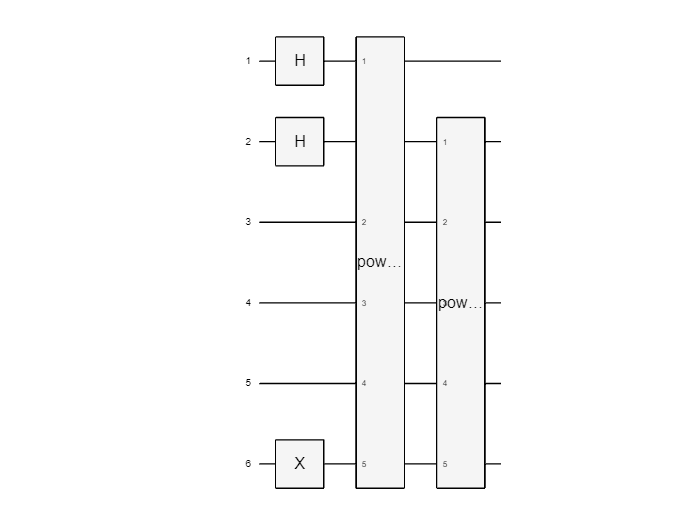

function U = controlled_compiled_amod15(pow, mapping)
    % CONTROLLED_COMPILED_AMOD15: Controlled modular exponentiation for N=15.
    % Inputs:
    %   pow: The exponentiation power
    %   mapping: The association between the index of external and internal qubits
    % Output:
    %   U: Controlled Modular Exponentiation Gate.

    gates = [];
    
    % Declaring the function of the Qubits involved
    control_qubit = 1;
    target_qubits = [2, 3, 4, 5];

    for iteration = 1:pow
        % Controlled SWAP(4,5)
        gates = [gates, ccxGate(control_qubit, 4, 5)];
        gates = [gates, ccxGate(control_qubit, 5, 4)];
        gates = [gates, ccxGate(control_qubit, 4, 5)];
        
        % Controlled SWAP(3,4)
        gates = [gates, ccxGate(control_qubit, 3, 4)];
        gates = [gates, ccxGate(control_qubit, 4, 3)];
        gates = [gates, ccxGate(control_qubit, 3, 4)];
        
        % Controlled SWAP(2,3)
        gates = [gates, ccxGate(control_qubit, 2, 3)];
        gates = [gates, ccxGate(control_qubit, 3, 2)];
        gates = [gates, ccxGate(control_qubit, 2, 3)];
        
        % Controlled X gates on qubits 2:5
        for q = target_qubits
            gates = [gates, cxGate(control_qubit, q)];
        end
    end
    
    name = strcat("pow_7_", string(pow), "_mod15");

    U = compositeGate(gates, mapping, "Name", name); % 7^Pow % 15
end

#### 3.4.2 A Running Example of Pow(7,x) Mod 15 

The following script empirically shows that the quantum implementation of the modular exponentiation for $7^x \;\textrm{Mod}\;15$, which we have just implemented, works.

The circuit uses two control qubits $\left(1:2\right)$ to pilot the computation of $7^1 \;\textrm{Mod}\;15$  and $7^2 \;\textrm{Mod}\;15$, with the result stored in the target qubits $\left(3:6\right)$.

The Hadamard gates prepare the control qubits in superposition, which allow the circuit to compute any linear combination of the exponent value $x=q_1 *2^0 +q_2 *2^1$, which yields $\left\lbrace 0,\;1,\;2,\;3\right\rbrace$.

The X-Gate initializes the low registers to $|1\rangle$.

The following example circuit, in fact, is a small circuit which relies on the same logic we will use to build the full circuit later on. 

first_exponentiation_mapping  = [1, 3, 4, 5, 6];
second_exponentiation_mapping = [2, 3, 4, 5, 6];

example_circuit = quantumCircuit( ...
        [hGate(1), hGate(2), xGate(6), ...
        controlled_compiled_amod15(1, first_exponentiation_mapping), ...
        controlled_compiled_amod15(2, second_exponentiation_mapping)], ...
        6);

example_circuit.plot()

measure = simulate(example_circuit, "000000");

M = randsample(measure, 1024);


     State      Probability    ControlQubits    Values    Values_Decimal
    ________    ___________    _____________    ______    ______________

    "000001"      0.24121          "00"         "0001"         "1"      
    "010100"      0.23828          "01"         "0100"         "4"      
    "100111"      0.25293          "10"         "0111"         "7"      
    "111101"      0.26758          "11"         "1101"         "13"     



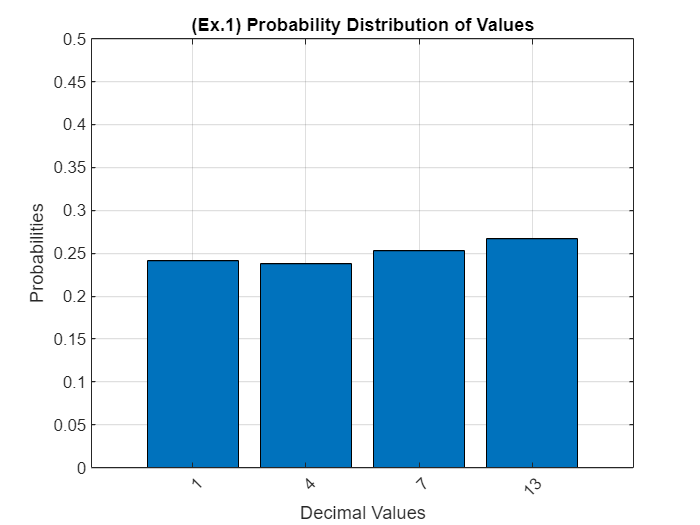

T = table(M.MeasuredStates, M.Probabilities, 'VariableNames', ...
        {'State', 'Probability'});

for i = 1:height(T)
    originalState = T.State(i);
    controlQubits = extractBetween(originalState, 1, 2);
    upperRegState = extractBetween(originalState, 3, strlength(originalState));
    T.ControlQubits(i) = string(controlQubits);
    T.Values(i) = string(upperRegState);
    T.Values_Decimal(i) = string(bin2dec(upperRegState));
end

disp(T);


stateOrder = string(sort(str2double(T.Values_Decimal)));

figure;
bar(categorical(T.Values_Decimal, stateOrder), T.Probability);

xlabel('Decimal Values');
ylabel('Probabilities');
title('(Ex.1) Probability Distribution of Values');
ylim([0 0.5]);
xtickangle(45);

grid on;

## 4 Factoring N = 15 applying Shor's Algorithm using MATLAB Quantum Package

Let's create a concrete application of the algorithm by integrating all the components we have built.

We begin by selecting a base value $a=7$, which is relatively prime to $N$ (they share no common factors). This is an essential requirement for Shor's algorithm to work properly.

Our sub-goal is to find the order of $r$ of $x$ with respect to $N$. By using the order-finding algorithm:

we start with the quantum state $|0\rangle$$|0\rangle$  where the first register will store superpositions for the phase estimation and the second will hold powers of a. By applying $t=8$ Hadamard gates to the first register, we create an equal superposition of all possible states::


$$\frac{1}{\sqrt{2^t }}\sum_{k=0}^{2^t -1} |k\rangle |0\rangle =\frac{1}{\sqrt{2^t }}\left\lbrack |0\rangle +|1\rangle +|2\rangle +\;\ldotp \ldotp \ldotp +|2^t -1\rangle \right\rbrack \;$$

$$|0\rangle$$


This superposition gives us a probability $\epsilon$ of at most  $\frac{1}{2}$ for measuring the correct value that will lead to $r$.

Next, we compute $U\left(a\right):|x_i \rangle \;|0\rangle \to |x_i \rangle \;|a^x \;\textrm{mod}\left(N\right)\rangle$, which stores in the second register the value of $a^x \;\textrm{mod}\left(N\right)$ for each state ${|x}_i \rangle$ in the superposition:


$$\frac{1}{\sqrt{2^t }}\sum_{k=0}^{2^t -1} |k\rangle |x^k \;\textrm{mod}\;N\rangle =\frac{1}{\sqrt{2^t }}\left\lbrack |0\rangle |1\rangle +|1\rangle |7\rangle +|2\rangle |4\rangle +|3\rangle |13\rangle +|4\rangle |1\rangle +|5\rangle |7\rangle +|6\rangle |4\rangle +\;\ldotp \ldotp \ldotp \;\right\rbrack \;$$


We now apply the Inverse Quantum Fourier Transform $\left({\textrm{QFT}}^{\dagger} \right)$ to the first register and measure it. Since we don't need to perform further operations on the second register, we can apply the *Principle of Implicit Measurement *and assume that the second register is measured, obtaining a *random *result from the set$\left\lbrace 1,4,7,13\right\rbrace$. 

Suppose that we obtain any value $x$ from the measurement. This implies that the input state to $\left({\textrm{QFT}}^{\dagger} \right)$ would have been:

 $\sqrt{\frac{1}{2^t }}\left\lbrack \textrm{all}\;\textrm{the}\;\textrm{terms}\;\textrm{of}\;\textrm{the}\;\textrm{expansion}\;\textrm{of}\;\textrm{the}\;\textrm{form}\;|k\rangle |x\rangle \;\right\rbrack$, 

which can be rewritten as:

 $\sqrt{\frac{x}{2^t }}\left\lbrack \textrm{all}\;\textrm{the}\;\textrm{left}\;\textrm{side}\;\textrm{kets}\;|k\rangle \right\rbrack$.

In our specific case, applying the transformation yields the probability distribution shown in the chart (Shor.1).

The final measurement gives either $0,64,128,192$, each with a probability close to $\frac{1}{4}\ldotp$

By obtaining a candidate value from the measurement and computing the continued fraction expansion, we eventually determine $r=4$ as the order of $x=7\ldotp \;$This is because, $r$ is even and $x^{\frac{r}{2}} \;\textrm{mod}\;N=7^2 \;\textrm{mod}\;15=4\not= -1\;\textrm{mod}\;15$. 

Finally, we compute


$$\begin{array}{l}
\gcd \left(x^2 -1,15\right)=\gcd \left(7^2 -1,15\right)=\gcd \left(48,15\right)=3\\
\gcd \left(x^2 +1,15\right)=\gcd \left(7^2 +1,15\right)=\gcd \left(50,15\right)=5
\end{array}$$
 

Therefore, we have found our candidate factors $p=5$and $q=3$ which indeed multiply to give $N=15=p\cdot q=5\cdot 3$.

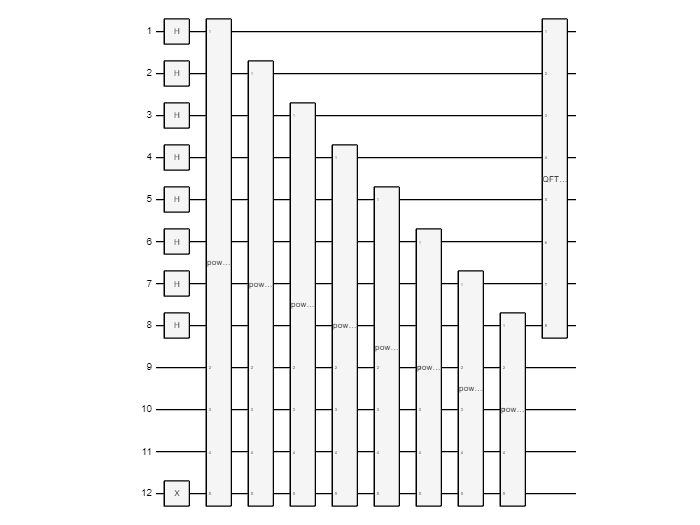


% Shor's Algorithm Implementation for N = 15 and a = 7
% The circuit consists of:
% 1. A superposition of exponent states using Hadamard gates.
% 2. Modular exponentiation to compute a^x mod N.
% 3. An inverse Quantum Fourier Transform (QFT†) to extract the period.
% 4. Classical post-processing to estimate the period and factorize N.

% Parameters:
N = 15;       % The number to factorize. 
a = 7;        % The base for modular exponentiation. 

n = ceil(log2(N));       % Number of Qubits - Down Register (Controlled Modular Exponentiation).
num_phase_qubits = 2*n;  % Phase estimation register size - Up Register (Inverse QFT).

gates = [];   % Array to store the quantum gates in the circuit.

% Step 1: Create superposition in the exponent register
% Apply Hadamard gates to all qubits in the exponent register.
for q = 1:num_phase_qubits
    gates = [gates, hGate(q)];
end

% Step 2: Initialize the target register for modular exponentiation
% Set the target register to |1⟩ by applying an X gate to the last qubit.
gates = [gates, xGate(num_phase_qubits + n)];

% Step 3: Perform controlled modular exponentiation
% For each qubit in the exponent register, apply controlled modular
% exponentiation gates to compute a^(2^(q-1)) mod N.

% Associating the down register qubits to be used in the
% controlled modular exponentiation
down_reg_mapping = [];
for q = 1:n
    down_reg_mapping = [down_reg_mapping, 2*n + q];
end

for q = 1:num_phase_qubits
    mapping = [q, down_reg_mapping]; % Qubit mapping for controlled operations
    gates = [gates, controlled_compiled_amod15(2^(q-1), mapping)];

end

% Step 4: Apply the inverse Quantum Fourier Transform (QFT†)
% The QFT† is applied to the exponent register to extract the period.
mapping = [1:num_phase_qubits]; % Qubit mapping for the QFT†
gates = [gates, qftDaggerGate(num_phase_qubits, mapping)];

% Step 5: Create and plot the quantum circuit
qc = quantumCircuit(gates, num_phase_qubits + n, "Name", "Shor");
qc.plot();

% Step 6: Simulate the circuit and sample measurements
% Simulate the circuit with an initial state of all zeros.
s = simulate(qc, "000000000000");
M = randsample(s, 2048); % Sample 2048 measurements

% Step 7: Process the measurement results
% Store the measured states and their probabilities.
T = table(M.MeasuredStates, M.Probabilities, 'VariableNames', {'MeasuredStates', 'Probabilities'});

% Truncate the measured states to remove the target register qubits.
T.UpperRegStates = strings(height(T), 1);
for i = 1:height(T)
    originalState = T.MeasuredStates(i);
    upperRegState = extractBetween(originalState, 1, strlength(originalState)-n);

      States      Probabilities
    __________    _____________

    "00000000"       0.25244   
    "01000000"       0.24658   
    "10000000"       0.25781   
    "11000000"       0.24316   



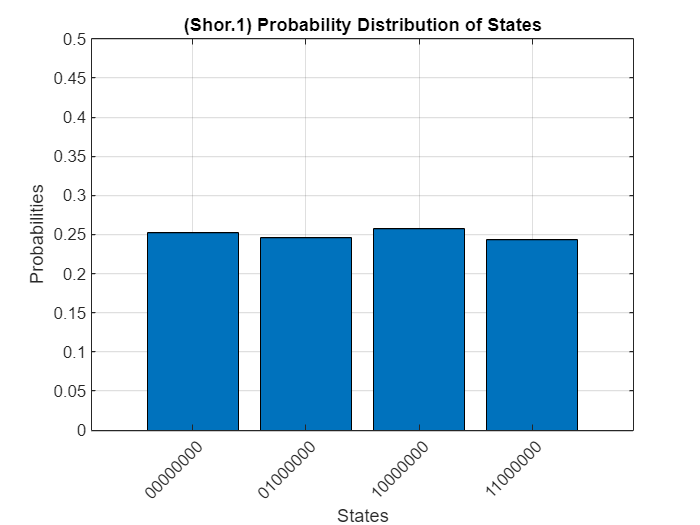

    T.UpperRegStates(i) = string(fliplr(char(upperRegState))); % Reverse for little-endian
end

% Group and sum probabilities for each state (Upper Register).
G = groupsummary(T, 'UpperRegStates', 'sum', 'Probabilities');
qftResults = G(:, {'UpperRegStates', 'sum_Probabilities'});
qftResults.Properties.VariableNames = {'States', 'Probabilities'};

% Display the results
disp(qftResults);


% Step 8: Plot the probability distribution of states
figure;
bar(categorical(qftResults.States), qftResults.Probabilities);
xlabel('States');
ylabel('Probabilities');
title('(Shor.1) Probability Distribution of States');
ylim([0 0.5]);
xtickangle(45);
grid on;

% Step 9: Classical post-processing to estimate the period
% Use continued fractions to estimate the period from the measured states.
numerical_values = continued_fraction_period(bin2dec(qftResults.States), 2^num_phase_qubits);

% Step 10: Attempt factorization using the estimated period
for i = 1:size(numerical_values, 1)
    r = numerical_values(i); % Estimated period
    fprintf('  Estimated Period (r): %d\n', r);
        
    % Check if the period is even
    if mod(r, 2) == 0
        x = a^(r/2);
            
        % Compute potential factors using gcd
        p = gcd(x + 1, N);

  Estimated Period (r): 1
  Estimated Period (r): 4


  Candidate Factors: 5, 3


        q = gcd(x - 1, N);
                
        % Validate factors
        if p > 1 && p < N && q > 1 && q < N
            fprintf('  Candidate Factors: %d, %d\n', p, q);
            factors = [p, q];
            return; % Exit if valid factors are found
        end
    end
end

## 5 Physical Implementation

Contemporary quantum computer face significant challenges due to high error rates and insufficient qubits for implementing quantum error correction. As a result, laboratory demonstrations of quantum algorithms often yields correct result only in a fraction of attempts.

In 2001, a team at IBM demonstrated Shor's Algorithm by factoring $15$ into $3 \cdot 5$, using a seven qubits quantum computer. Following this, two independent groups implemented Shor's Algorithm with photonic qubits, highlighting the observation of multi-qubit entanglement during the execution of the algorithm. In 2012, solid-state qubits were used to factor $15$, and later that year, the factorization of $21$ was achieved. However, a 2019 attempt to factor $35$ using Shor's algorithm on IBM's Q System One failed due to accumulating errors.

It is important to note that these demonstrations often relied on prior knowledge of the correct answer, and, in some cases, oversimplified the algorithm to the point of being equivalent to random guessing.

Theoretical analyses of Shor's algorithm assume a quantum computer free of noise and errors. In practice, near-term implementations must contend with such undesired phenomena. While quantum error correction could mitigate these issues when more qubits become available, it is not currently feasible.

In 2023, Jin-Yi Cai, a Chinese American mathematician and computer scientist showed that in presence of noise, Shor's algorithm fails asymptotically almost surely for large semi-primes that are product of two primes in OEIS sequence A073024. These primes $p$ have the property that $p-1$ has a prime factor larger than $p^{\frac{2}{3}}$, and have a positive density in the set of all primes. Consequently, robust error correction will be necessary for Shor's algorithm to reliably factor all numbers.

## 6 Performance Analysis

### 6.1 Computational Complexity of Shor's Algorithm

Shor's algorithm achieves a significant reduction in the time complexity of integer factorization compared to classical algorithms. The algorithm operates in polynomial time, specifically $\mathcal{O}({log}^3N)$, where $N$ is the integer to be factorized. This contrasts with the exponential time complexity of the best-known classical algorithms.

### 6.2 Comparison with Classical Factorization Algorithms

Classical factorization algorithms include trial division, Pollard’s rho, and the general number field sieve (GNFS):

- **Trial Division**: Operates with $\mathcal{O}(\sqrt N)$ complexity, making it impractical for large $N$.

- **Pollard’s Rho Algorithm**: More efficient for smaller numbers but still unsuitable for cryptographic-scale integers.

- **GNFS (General Number Field Sieve)**: The most efficient classical algorithm for large numbers, with sub-exponential complexity 

    
$$\mathcal{O}(e^{\sqrt[3]{\frac{64}{9}}(\log{N})^{\frac{1}{3}}(\log{\log{N}})^{\frac{2}{3}}}).$$


To visually compare the performance of Shor’s algorithm with the General Number Field Sieve (GNFS) and the Trial Division algorithm, we created a graph using MATLAB. The graph plots the computational time required by all three algorithms for factorizing integers of varying sizes.

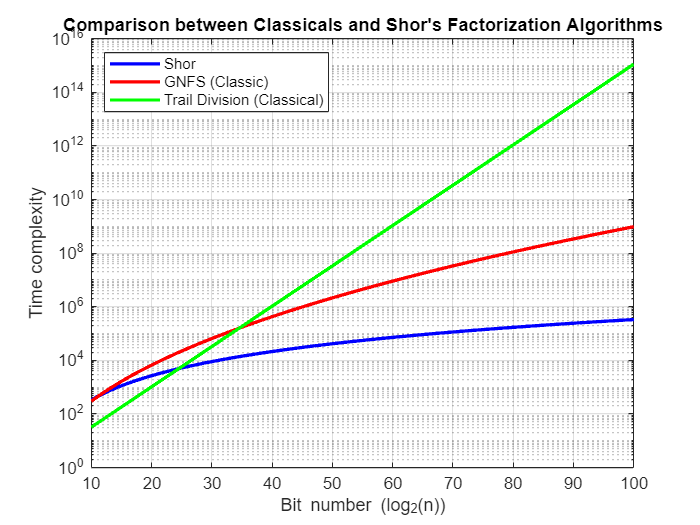

% MATLAB script to compare the time complexity of Shor's and GNFS algorithms
clc; clear;

% Range of n values (number of bits)
n_bits = 10:100; % Number of bits from 10 to 100
n_values = 2.^n_bits; % Corresponding values of n

% Time complexity function for Trial Division
trial_complexity = @(n) sqrt(n);

% Time complexity function for Shor's algorithm
shor_complexity = @(n) (log(n)).^3;

% Time complexity function for GNFS
gnfs_complexity = @(n) exp((64/9)^(1/3) * (log(n)).^(1/3) .* (log(log(n))).^(2/3));

% Calculate the complexity values
shor_values = shor_complexity(n_values);
trial_values = trial_complexity(n_values);
gnfs_values = gnfs_complexity(n_values);

% Plot the results
figure;
semilogy(n_bits, shor_values, 'b', 'LineWidth', 2);
hold on;
semilogy(n_bits, gnfs_values, 'r', 'LineWidth', 2);
hold on;
semilogy(n_bits, trial_values, 'g', 'LineWidth', 2);
hold off;


% Add titles and legend
title('Comparison between Classicals and Shor''s Factorization Algorithms');
xlabel('Bit number (log_2(n))');
ylabel('Time complexity');
legend('Shor', 'GNFS (Classic)', 'Trail Division (Classical)', 'Location', 'northwest');
grid on;
% Note: The logarithmic scale on the y-axis is used to better visualize the differences

## 7 Applications and Implications

### 7.1 Impact on Modern Cryptography

Shor's algorithm has profound implications for the security of modern cryptographic systems, particularly those relying on the hardness of integer factorization and discrete logarithm problems. RSA, one of the most widely used public-key cryptosystems, directly depends on the difficulty of factoring large integers.

- **RSA Cryptography**:  named after its inventors Ron Rivest, Adi Shamir, and Leonard Adleman, is a widely used public-key cryptosystem that relies on the computational difficulty of factoring large integers. The security of RSA is built on the premise that while multiplying two large prime numbers is computationally straightforward, the reverse process (factorizing their product) is exceedingly hard using classical algorithms. If an adversary can efficiently factorize $N$, they can break the RSA encryption by deriving the private key [4].

- **Elliptic Curve Cryptography (ECC)**: ECC, which relies on the difficulty of solving the elliptic curve discrete logarithm problem, is also vulnerable to Shor's algorithm. Quantum computers would be able to solve these problems efficiently, posing a threat to both symmetric and asymmetric cryptographic systems that rely on ECC [5].

## 8 Conclusion

In conclusion, Shor’s algorithm represents a groundbreaking milestone in quantum computing, showcasing how quantum computers can surpass classical methods in integer factorization. This capability directly threatens the security of modern cryptographic systems, such as RSA and ECC, which rely on the computational difficulty of problems that Shor’s algorithm solves in polynomial time. Although current implementations are constrained by errors and hardware requirements, advancements in quantum error correction and the development of more powerful quantum computers could make these threats a reality in the future.

## `9 Acknowledgments`

### `9.1 Books and Resources`

Nielsen, M. A., Chuang, I. L. *“Quantum Computation and Quantum Information. Cambridge University Press”*.

Rieffel, E, Polak, K. *"Quantum Computing - A Gentle Introduction. The MIT Press"*

Barletta Luca, Magarini Maurizio, *“Lecture Notes - Quantum Information Processing 101”, Politecnico di Milano*.

Marco Venere, *“Quantum Computing - A Practical Perspective”, Politecnico di Milano*.

### `9.2 Articles `

[1] V. Vedral, A. Barenco, A. Ekert, (1995) [*"Quantum Networks for Elementary Arithmetic Operations"*](https://arxiv.org/abs/quant-ph/9511018)

[2] S. Beauregard, (2003) [*"Circuit for Shor's algorithm using 2n+3 qubits"*](https://doi.org/10.48550/arXiv.quant-ph/0205095)

[3] O. Gamel, D. F. V. James, (2013) [*"Simplified Factoring Algorithms for Validating Small-Scale Quantum Information Processing Technologies"*](https://doi.org/10.48550/arXiv.1310.6446)

[4] Rivest, R. L., Shamir, A., Adleman, L. (1978) [*“A Method for Obtaining Digital Signatures and Public-Key Cryptosystems. Communications of the ACM”*](https://doi.org/10.1145/359340.359342).

[5] Shor, P. W. (1994). [*“Algorithms for Quantum Computation: Discrete Logarithms and Factoring. Proceedings of the 35th Annual Symposium on Foundations of Computer Science”*](https://doi.org/10.1109/SFCS.1994.365700).

### `9.3 Other Useful Websites `

[https://csrc.nist.gov](https://csrc.nist.gov)

[https://www.ibm.com/quantum/qiskit](https://www.ibm.com/quantum/qiskit)

[https://learning.quantum.ibm.com/course/fundamentals-of-quantum-algorithms/phase-estimation-and-factoring](https://learning.quantum.ibm.com/course/fundamentals-of-quantum-algorithms/phase-estimation-and-factoring)

[https://learning.quantum.ibm.com/course/practical-introduction-to-quantum-safe-cryptography/asymmetric-key-cryptography#shors-quantum-algorithm-and-rsa](https://learning.quantum.ibm.com/course/practical-introduction-to-quantum-safe-cryptography/asymmetric-key-cryptography#shors-quantum-algorithm-and-rsa)